# A Guide to MATLAB

## Chapter 2: MATLAB basics

### Basic commands

clear % clear workspace variables
clc % clear command window
help general % help on general purpose commands

  General purpose commands.
  MATLAB Version 9.11 (R2021b) 14-May-2021 
 
  General information.
    syntax        - Help on MATLAB command syntax.
    demo          - Run demonstrations.
    ver           - MATLAB, Simulink and toolbox version information.
    version       - MATLAB version information.
    verLessThan   - Compare version of toolbox to specified version string.
    logo          - Plot the L-shaped membrane logo with MATLAB lighting.
    membrane      - Generates the MATLAB logo.
    bench         - MATLAB Benchmark.
  
  Managing the workspace.
    w

help factor % brief info about factor command

 factor Prime factors.
    factor(N) returns a vector containing the prime factors of N.
 
    This function uses the simple sieve approach. It may require large
    memory allocation if the number given is too big. Technically it is
    possible to improve this algorithm, allocating less memory for most
    cases and resulting in a faster execution time. However, it will still
    have problems in the worst case.
  
    Class support for input N:
       float: double, single
       integer: uint8, int8, uint16, int16, uint32, int32, uint64, int64
 
    See also primes, isprime.

    Documentation for factor
    Other functions named factor



lookfor cosine % search the first line of help file for string 'cosine'

acos                           - Inverse cosine, result in radians.
acosd                          - Inverse cosine, result in degrees.
acosh                          - Inverse hyperbolic cosine.
cos                            - Cosine of argument in radians.
cosd                           - Cosine of argument in degrees.
cosh                           - Hyperbolic cosine.
slsincos                       - This is a private mask helper file for sine and cosine blocks in 
slsincoslut                    - This is a private mask helper file for sine and cosine blocks in 
commdoc_rrc                    - Pulse Shaping Using a Raised Cosine Filter
angle2dcm       

format long % display 15 digits of floating-point numbers
format short % display 5 digits of floating-point numbers
help symbolic % make sure the symbolic toolbox is installed and show help on it

  Symbolic Math Toolbox
  Version 9.0 (R2021b) 14-May-2021
 
  Symbolic Objects
  ----------------
  Symbolic Variables & Expressions
    str2sym      - Evaluate string representing symbolic expression
    sym          - Create symbolic object.
    syms         - Short-cut for constructing symbolic objects
    symvar       - Short-cut for constructing symbolic objects
    symfun       - Create symbolic functions
    sympref      - Set symbolic preferences
    vpa          - Variable-precision arithmetic
 
  Operators and Elementary Operations
    minus        - -  subtraction.
    

vpa(sqrt(2), 30) % variable precision arithmetic

$$ans = 1.41421356237309504880168872421$$

echo on % display the statements inside script files
x = 1; % suppress the output by semicolon

### Symbolic computation

clear;
cos(pi/2) % machine approximation

ans = 6.1232e-17

cos(sym(pi/2)) % symbolic exact value

$$ans = 0$$

syms x y
expr = (x-y)*(x-y)^2

$$expr = {\left(x-y\right)}^{3}$$

expr_exp = expand(expr)

$$expr\_exp = x^{3}-3\,x^{2}\,y+3\,x\,y^{2}-y^{3}$$

factor(expr_exp)

$$ans = \left(\begin{array}{ccc} x-y & x-y & x-y \end{array}\right)$$

simplify((x^3-y^3)/(x-y))

$$ans = x^{2}+x\,y+y^{2}$$

syms u v
w = u^2 - v^2

$$w = u^{2}-v^{2}$$

subs(w, u, 2) % substitute value 2 for variable u in expression w

$$ans = 4-v^{2}$$

subs(w, v, 1)

$$ans = u^{2}-1$$

vpa(sqrt(2))

$$ans = 1.4142135623730950488016887242097$$

digits(8) % set variable precision digits for vpa
vpa(sqrt(2))

$$ans = 1.4142136$$

digits(32) % default value for vpa is 32

### Vectors

clear;
z = [1, 2, 3] % vector elements separated by commas

z =      1     2     3


y = [4 -3 5 -2 8 1] % vector elements separated by spaces

y =      4    -3     5    -2     8     1


x = 1:9 % create vector of numbers running from 1 to 9 with increment 1

x =      1     2     3     4     5     6     7     8     9


j = 0:2:10 % from 0 to 10 with increment 2

j =      0     2     4     6     8    10


i = 0:0.1:1 % increment 0.1

i =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


k = 10:-1:1 % negative increment

k =     10     9     8     7     6     5     4     3     2     1


j(1) % extract element of a vector

ans = 0

x' % transpose

ans =      1
     2
     3
     4
     5
     6
     7
     8
     9


x.^2 % elementwise square

ans =      1     4     9    16    25    36    49    64    81


j.*y % elementwise multiplication

ans =      0    -6    20   -12    64    10


exp(z) % elementwise exponentiation

ans =     2.7183    7.3891   20.0855


### Matrices

clear;
A = [1, 2, 3, 4; 5, 6, 7, 8; 9, 10, 11, 12]

A =      1     2     3     4
     5     6     7     8
     9    10    11    12


B = [1 2; 3 4; 5 6; 7 8]

B =      1     2
     3     4
     5     6
     7     8


C = A*B % matrix product

C =     50    60
   114   140
   178   220


A*2 % multiplication by scalar

ans =      2     4     6     8
    10    12    14    16
    18    20    22    24


B.*[1 2 3 4]' % elementwise multiplication of matrix by vector with broadcasting

ans =      1     2
     6     8
    15    18
    28    32


### Functions

clear;
log(exp(3)) % natural logarithm

ans = 3

tan(sym(pi/2)) % use symbolic argument for exact answer

$$ans = \infty$$

f = @(x) x^2 % user-defined anonymous function

f = function_handle with value:
    @(x)x^2


f(3) % evaluate a funciton

ans = 9

f = @(x) x.^2 % enable elementwise operation on vectors

f = function_handle with value:
    @(x)x.^2


f(1:5) % evaluate a funciton on vector

ans =      1     4     9    16    25


g = @(x, y) x.^2 + y.^2 % define function of two or more variables

g = function_handle with value:
    @(x,y)x.^2+y.^2


g(1,2) % evaluate a multivariable function

ans = 5

g([1 2], [3 4]) % also possible to pass a vector to it

ans =     10    20


### Managing variables

clear;
a = pi

a = 3.1416

b = 'pi'

b = 'pi'

c = sym(pi)

$$c = \pi$$

d = 5

d = 5

e = sqrt(-1)

e = 0.0000 + 1.0000i

f = @(x) x.^2 % anonimous function declaration

f = function_handle with value:
    @(x)x.^2


whos % get information about variables

  Name      Size            Bytes  Class              Attributes

  a         1x1                 8  double                       
  b         1x2                 4  char                         
  c         1x1                 8  sym                          
  d         1x1                 8  double                       
  e         1x1                16  double             complex   
  f         1x1                32  function_handle              



### Solving equations

clear;
syms x;
solve(x^2 - 2*x - 4 == 0)

$$ans = \left(\begin{array}{c} 1-\sqrt{5}\\ \sqrt{5}+1 \end{array}\right)$$

solve(x^2 - 2*x - 4) % we can omit == 0

$$ans = \left(\begin{array}{c} 1-\sqrt{5}\\ \sqrt{5}+1 \end{array}\right)$$

double(ans) % get a numerical solution instead of symbolic one

ans =    -1.2361
    3.2361


solve(x^2==3*x-7) % solution is a complex number

$$ans = \left(\begin{array}{c} \frac{3}{2}-\frac{\sqrt{19}\,\mathrm{i}}{2}\\ \frac{3}{2}+\frac{\sqrt{19}\,\mathrm{i}}{2} \end{array}\right)$$

vpa(ans, 5)

$$ans = \left(\begin{array}{c} 1.5-2.1794\,\mathrm{i}\\ 1.5+2.1794\,\mathrm{i} \end{array}\right)$$

syms y;
solve(2*x-log(y)==1, y) % solve for y in terms of x

$$ans = {\mathrm{e}}^{2\,x-1}$$

[xsol, ysol] = solve(x^2-y==2, y-2*x==5) % specify more than one equation

$$xsol = \left(\begin{array}{c} 1-2\,\sqrt{2}\\ 2\,\sqrt{2}+1 \end{array}\right)$$

$$ysol = \left(\begin{array}{c} 7-4\,\sqrt{2}\\ 4\,\sqrt{2}+7 \end{array}\right)$$

[xsol(1) ysol(1)] % an order pair (x,y) of the first solution

$$ans = \left(\begin{array}{cc} 1-2\,\sqrt{2} & 7-4\,\sqrt{2} \end{array}\right)$$

sol = solve(x^2-y==2, y-2*x==5) % not assigning solutions to a vector

sol = struct with fields:
    x: [2×1 sym]
    y: [2×1 sym]


sol.x(1) % extract individual value from the solution vector

$$ans = 1-2\,\sqrt{2}$$

solve(sin(x)==2-x) % this equation cannot be solved symbolically

$$ans = 1.1060601577062719106167372970301$$

digits(10), solve(log10(x) == cos(x)) % more than one solution is hidden

$$ans = -226.7493799+1.678107548\,\mathrm{i}$$

solve(log10(x) == cos(x), x, 'Real', true) % return only real roots

 
ans =
 
Empty sym: 0-by-1
 


syms x real % all future symbolic commands will treat x as real
assume(x, 'real') % is the same command, persists until `assume(x, 'clear')`
assumptions % display all current assumptions

$$ans = x\in \mathbb{R}$$

solve(log10(x) == cos(x))

$$ans = 5.552112002$$

fzero(@(x) log10(x) - cos(x), 2) % find an approximate solution near x=2

ans = 1.4184

assume(x>6) % for x>6
solve(log10(x) == cos(x)) % find a root

$$ans = 6.863082118$$

assume(x, 'clear') % clear x
assumptions % assumptions on x are cleared

 
ans =
 
Empty sym: 1-by-0
 


### Graphics

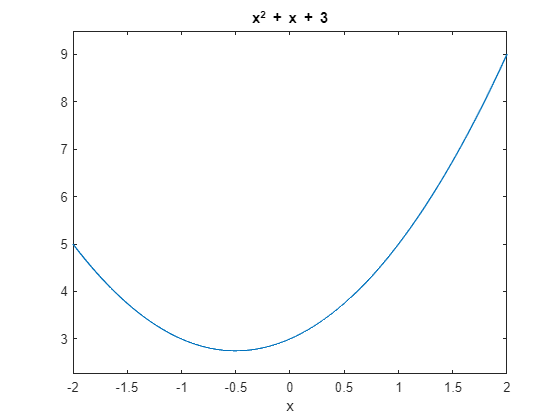

clear;
ezplot('x^2 + x + 3', [-2 2]) % the easiest way to plot a graph

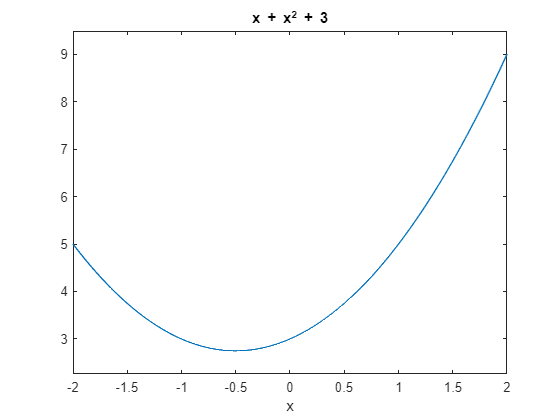

syms x, ezplot(x^2 + x + 3, [-2 2]) % the same using symbolic expression

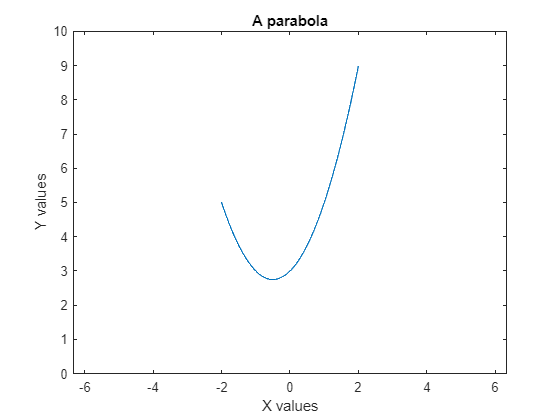

ezplot(@(x) x.^2 + x + 3, [-2 2]) % plot using anonymous function
title 'A parabola' % add a title
axis([-2 2 0 10]) % modify horizontal and vertical ranges
xlabel 'X values' % add x label
ylabel 'Y values' % add y label
axis equal % force the same scale on both axis

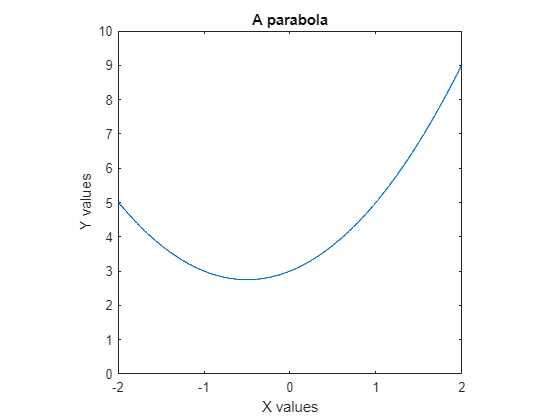

ezplot(@(x) x.^2 + x + 3, [-2 2]) % plot using anonymous function
title 'A parabola' % add a title
axis([-2 2 0 10]) % modify horizontal and vertical ranges
xlabel 'X values' % add x label
ylabel 'Y values' % add y label
axis square % make the shape of the graph square

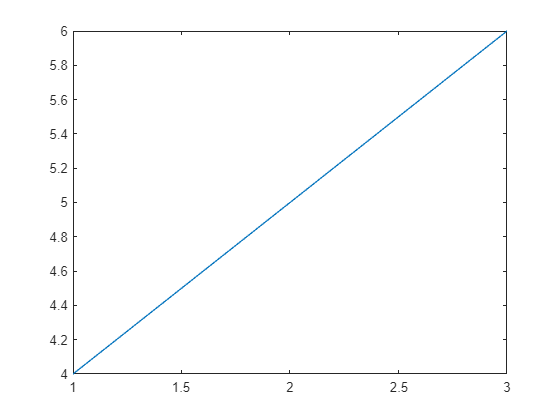

x = [1 2 3];
y = [4 5 6];
plot(x, y) % plot on vectors of numerical data

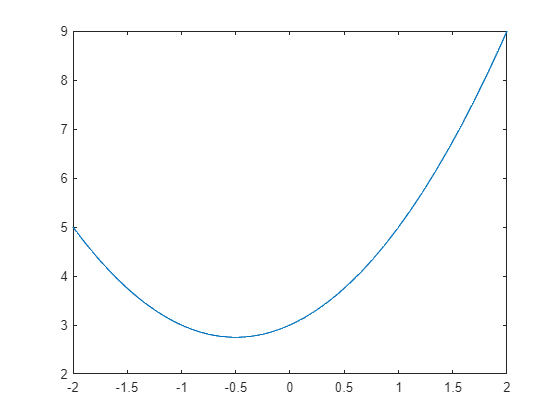

x = -2:0.01:2;
plot(x, x.^2+x+3)

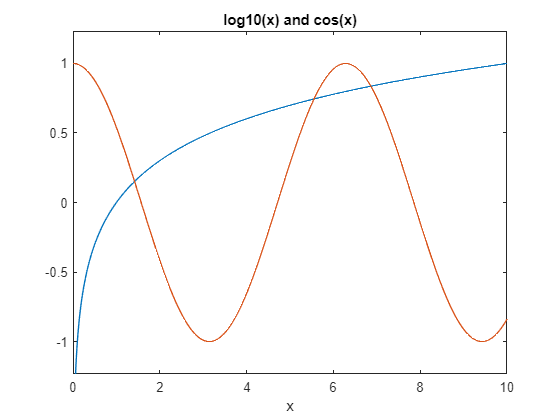

ezplot(@log10, [0 10]) % @ to use existing MATLAB functions
hold on % retain old graph and draw new graph on top of it
ezplot(@cos, [0 10])
hold off % stop overlaying graphs
title 'log10(x) and cos(x)'

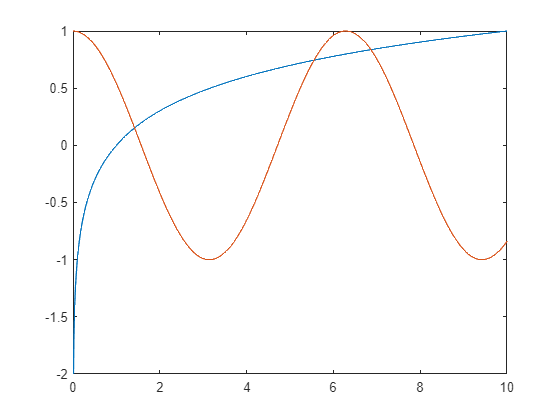

x = 0:0.01:10;
plot(x, log10(x), x, cos(x)) % plot multiple curves directly